# Lesson 2: collecting data from multiple files

Data files: [https://drive.google.com/file/d/1kwzy0HeYRou9QeiHVmkFYbIildTKhpWc/view?usp=sharing](https://drive.google.com/file/d/1kwzy0HeYRou9QeiHVmkFYbIildTKhpWc/view?usp=sharing)

Function for getting the images: [https://drive.google.com/file/d/1BcNXAMLo7hLsOLZH2Z2olaXHmey7TGTU/view?usp=sharing](https://drive.google.com/file/d/1BcNXAMLo7hLsOLZH2Z2olaXHmey7TGTU/view?usp=sharing) 

Function (not used, removes warnings): https://drive.google.com/file/d/1470nAUHy1v_BNOQNTslQ10R1hiId_qmM/view?usp=sharing  

Each file name has the following structure: geometry name + _P + period + _H + height.

periods = 300:50:400;
heights = 600:100:1000;
geom_names = {'post','post_inverted','mid_corner_circ',...
    'mid_corner_circ_inverted','4ellipses','4ellipses_inverted',...
    'cross','cross_inverted','4bars_rounded','4bars_rounded_inverted',...
    '2posts','2posts_inverted'};

Each file has a `data` matrix, size number of wavelength times number of geometries, vector of wavelength values and cell array of function handles that generate the images.

### Task 1. Get all the datafile names as a cell array using ls.

On Unix

list = ls('datafiles/simdata/*.mat'); % note file path may vary
list = split(list(1:end-1)); % remove newline character in the end

On Windows

list = ls('datafiles/simdata/*.mat'); % note file path may vary
% add additional padding with spaces
list = [list, repmat(' ',size(list,1),1)];
list = list.';
list = list(:).';
list = split(list, ' ');
% remove empty cells
list(cellfun(@isempty, list)) = [];
% delete '.' and '..' cells if needed
list(1:2) = []; % or list = list(3:end);

Or another simpler way for Windows

list = ls('datafiles/simdata/*.mat'); % note file path may vary
list = num2cell(list, 2); % put each row into a cell
list = cellfun(@strip, list, 'UniformOutput', false); % remove extra whitespaces
% this cellfun is totally equivalent to the following loop
% for i = 1:length(list)
%     list{i} = strip(list{i});
% end

### Task 2. Collect all the data for different paramters into one large matrix glued along the 'geometry' dimension.

data = [];
for i = 1:length(list)
    f = load(strip(list{i})); % extra strip for safety
    data = [data, f.data]; % ignore the warning
end

An alternative and somewhat quicker (therefore better) way of achieving the same. Notice, no warning this time

data = cell(size(list));
for i = 1:length(list)
    f = load(strip(list{i})); % extra strip for safety
    data{i} = f.data; 
end
data = [data{:}];

### Task 2a. For speed pre-load all the files into memory (possible for relatively small amounts of data).

% pre-allocate resources, by creating length(list) structures
f = struct('name', list, 'data', cell(size(list)), 'geom', cell(size(list)), 'wl', cell(size(list)));
for i = 1:length(f)
    tmp = load(f(i).name); 
    f(i).data = tmp.data;
    f(i).geom = tmp.geom;
    f(i).wl = tmp.wl;
end
% now, all data is in RAM, instead of being in disk

### Task 3. Plot phase scatter plots for all the data as in Lesson 1.

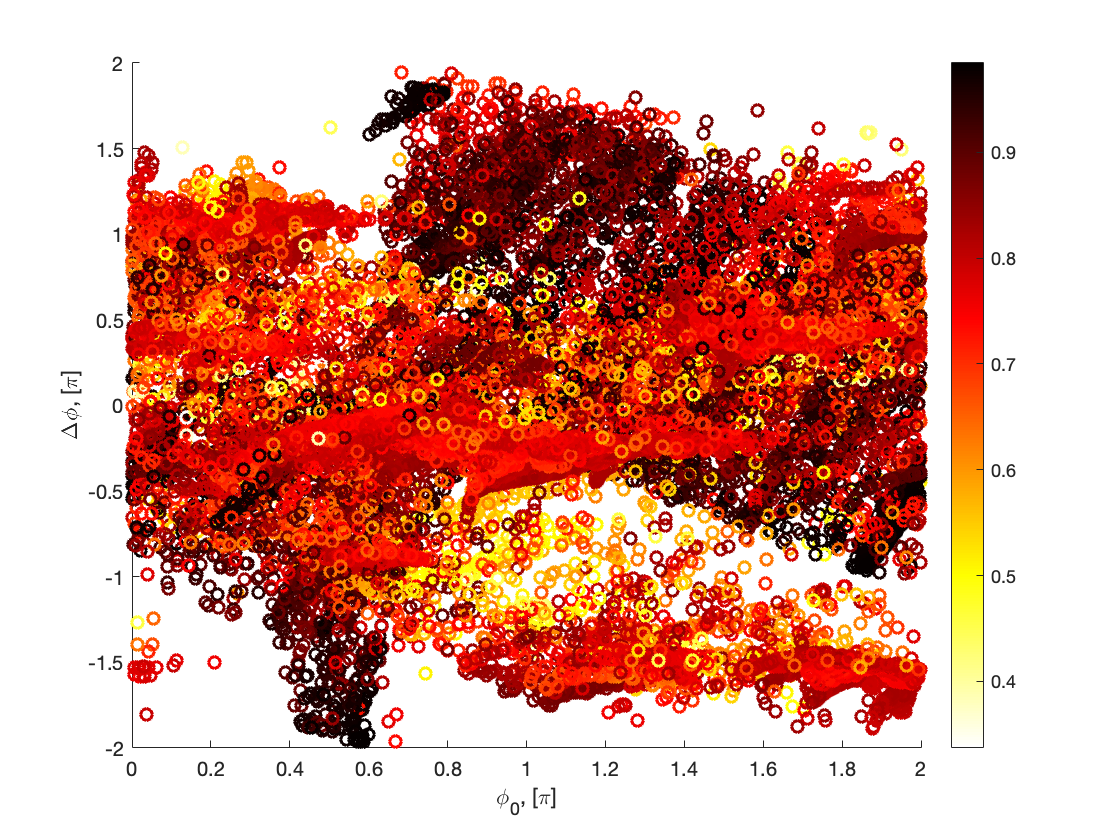

% Same as in Lesson 1 (Tasks 2 and 3), but define phase as angle of data and amp as abs of
% data.
wavelength = f(1).wl;
[phi0,delta_phi,ave] = get_phi_delta_phi(data, wavelength);

figure; scatter(phi0/pi, delta_phi/pi, 36, ave, "LineWidth", 1.5); 
colormap(flipud(hot)); colorbar
xlabel('\phi_0, [\pi]'); ylabel('\Delta\phi, [\pi]')

Show only high tranmission entries

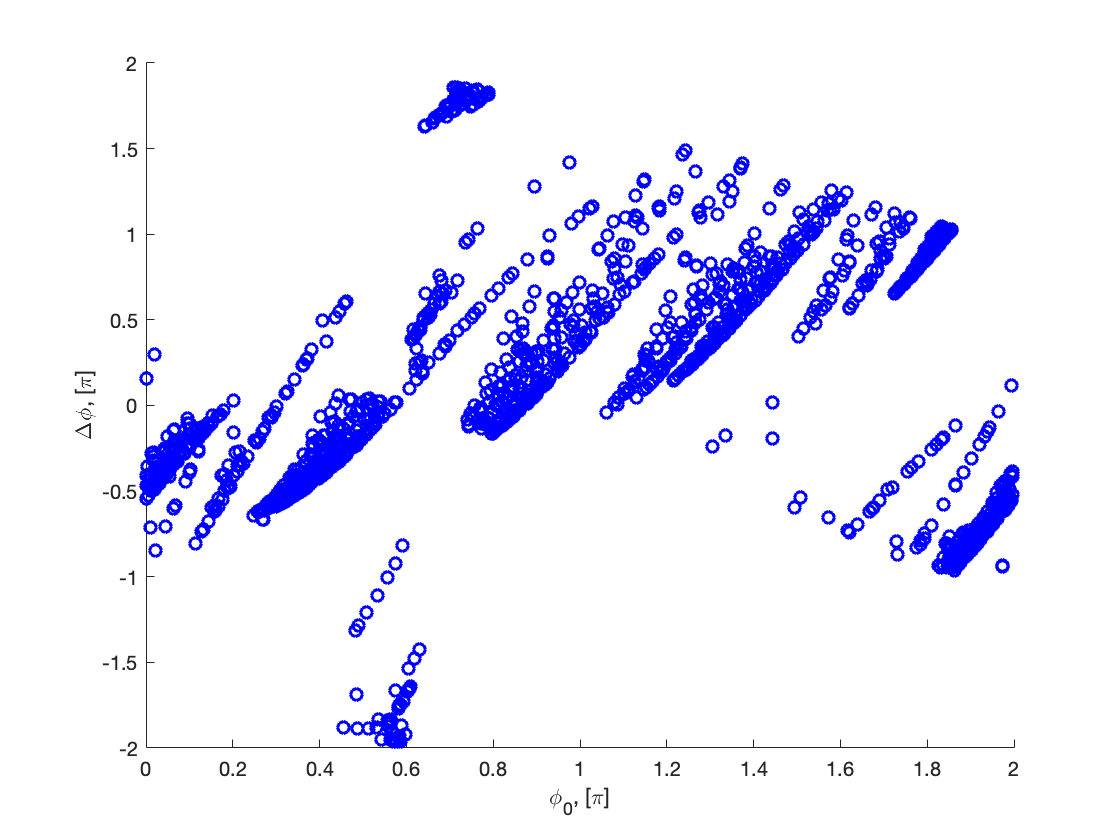

idx = ave > .97;
figure; scatter(phi0(idx)/pi, delta_phi(idx)/pi, 36, 'b', "LineWidth", 1.5); 
xlabel('\phi_0, [\pi]'); ylabel('\Delta\phi, [\pi]')

### Task 4. Make a scatter plot where in red we have 'non-iverted' geomtries, in blue -- 'inverted' ones.

% Hint: to filter out inverted geometries, in the for loop from Task 2 use
% contains(list{i},'inverted'). This checks if the filename contains the
% word "inverted". If it does, record the data to something like
% data_inverted array, instead of data.
% Hint 2: make same steps as in Task 3 (amp not needed, as color will be
% fixed)
tic
[data, data_inverted] = deal(cell(size(list)));
for i = 1:length(list)
    tmp = load(strip(list{i})); % extra strip for safety
    if contains(list{i},'inverted')
        data_inverted{i} = tmp.data;
    else
        data{i} = tmp.data;
    end
end
toc

Elapsed time is 5.921088 seconds.


### Task 4a. Do the same, but using the `f` struct array from Task 2a.

tic
[data, data_inverted] = deal(cell(size(f)));
for i = 1:numel(f)
    if contains(f(i).name,'inverted')
        data_inverted{i} = f(i).data;
    else
        data{i} = f(i).data;
    end
end
toc

Elapsed time is 0.005702 seconds.


data = [data{:}];
data_inverted = [data_inverted{:}];
wavelength = tmp(1).wl;
[phi0,delta_phi,ave] = get_phi_delta_phi(data, wavelength);
[phi0_inverted,delta_phi_inverted,ave_inverted] = get_phi_delta_phi(data_inverted, wavelength);

#### Plot the two matrices using different color

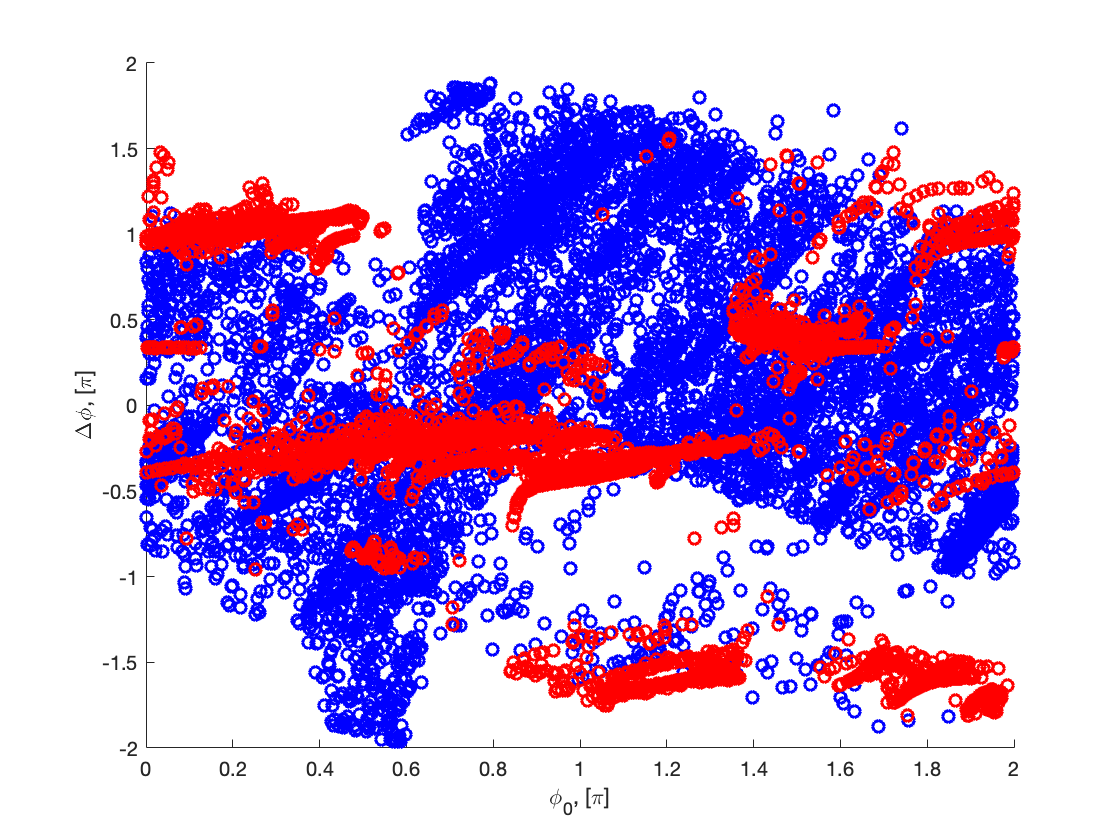

max_ave = .8;
idx = ave > max_ave;
idx2 = ave_inverted > max_ave;
figure
scatter(phi0(idx)/pi, delta_phi(idx)/pi, 36, 'b', "LineWidth", 1.5); 
xlabel('\phi_0, [\pi]'); ylabel('\Delta\phi, [\pi]')
hold on
scatter(phi0_inverted(idx2)/pi, delta_phi_inverted(idx2)/pi, 36, 'r', "LineWidth", 1.5); 
xlabel('\phi_0, [\pi]'); ylabel('\Delta\phi, [\pi]')

### Task 5. In a seprate subplots for inverted and non-inverted, colorcode data by height for a fixed period. Later, make a separate plot for each period. 

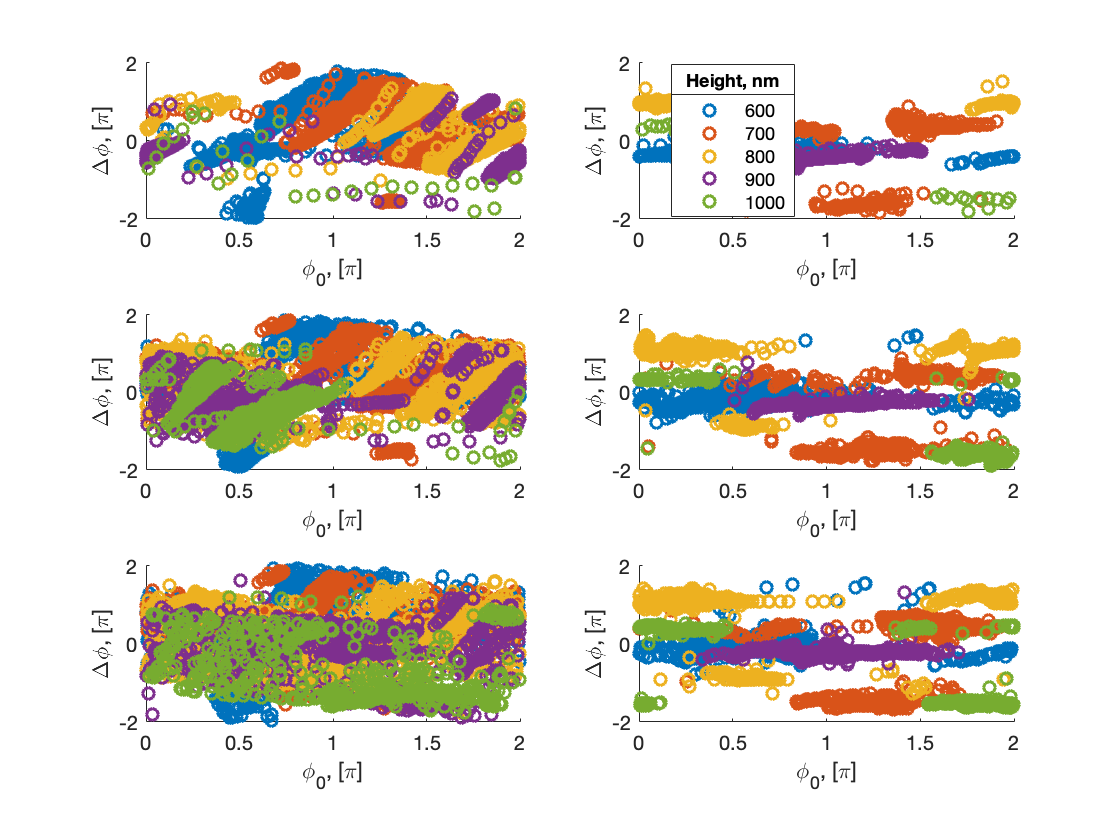

ind_fig = 1;
figure
for period = periods
    for hcurr = heights
        [data, data_inverted] = deal(cell(size(geom_names)));
        for iname = 1:length(geom_names)
            % folder path depends on your directory structure
            filename = ['datafiles/simdata/',geom_names{iname}, '_P', num2str(period), '_H', num2str(hcurr),'.mat'];
            if exist(filename,'file')
                tmp = load(filename); 
            end
            if contains(filename,'inverted')
                data_inverted{iname} = tmp.data;
            else
                data{iname} = tmp.data;
            end
        end
        data = [data{:}];
        data_inverted = [data_inverted{:}];
        [phi0,delta_phi,ave] = get_phi_delta_phi(data, wavelength);
        [phi0_inverted,delta_phi_inverted,ave_inverted] = get_phi_delta_phi(data_inverted, wavelength);
    
        max_ave = .0;
        idx = ave > max_ave;
        idx2 = ave_inverted > max_ave;
        
        subplot(numel(periods),2,ind_fig)
        scatter(phi0(idx)/pi, delta_phi(idx)/pi, 36, "LineWidth", 1.5); 
        xlabel('\phi_0, [\pi]'); ylabel('\Delta\phi, [\pi]')
        hold on
        subplot(length(periods),2,ind_fig+1)
        scatter(phi0_inverted(idx2)/pi, delta_phi_inverted(idx2)/pi, 36, "LineWidth", 1.5); 
        xlabel('\phi_0, [\pi]'); ylabel('\Delta\phi, [\pi]')
        hold on
    end
    if period == periods(1)
        lgd_str = split(num2str(heights));
        lgd = legend(lgd_str{:},'Location','best');
        title(lgd,'Height, nm')
    end
    ind_fig = ind_fig + 2;
end

### Task 5a. You guessed it! Do the same, but with the `f` cell array from Task 2a.

### Task 6. Create a new variable "material volume" and use it as color coding for the scatter plots.

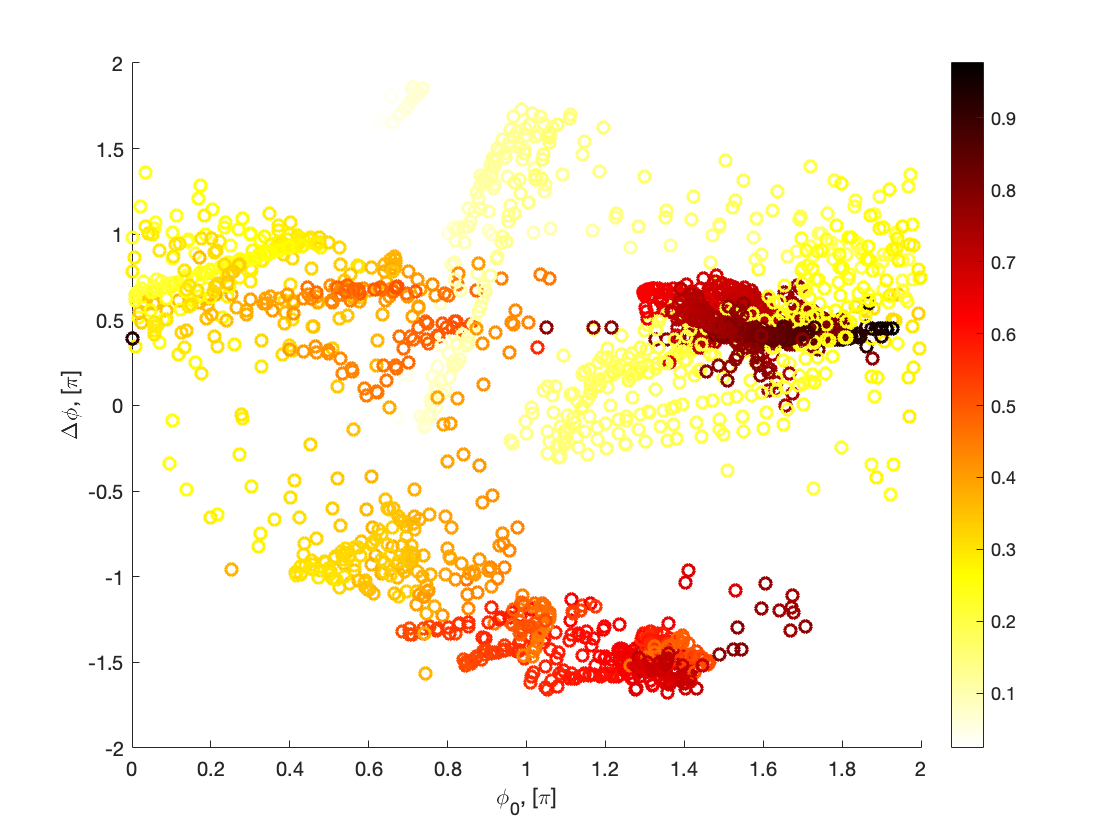

% TO DO AT HOME
% 1. Make two additional loops over periods and heights
% 2. gather all the data together, but instead of image fractions, frac,
% have volume fraction: frac*period^2*height
% 3. to use new volume fraction as a colordata, normalize it by max_volume
% = periods(end)^2*heights(end);
period = periods(3);
height = heights(2);
[data, frac] = deal(cell(size(geom_names)));
N = 200;
for iname = 1:length(geom_names)
    % folder path depends on your directory structure
    filename = ['datafiles/simdata/',geom_names{iname}, '_P', num2str(period), '_H', num2str(height),'.mat'];
    
    i = find(strcmp({f.name}, filename));
    if ~isempty(i)
        data{iname} = f(i).data;
        frac{iname} = zeros(1,length(f(i).geom));
        for j = 1:length(f(i).geom)
            tmp = f(i).geom{j}(N);
            frac{iname}(j) = sum(tmp(:))/numel(tmp);
        end
    end
end

data = [data{:}];
frac = [frac{:}];
[phi0,delta_phi,ave] = get_phi_delta_phi(data, wavelength);

figure
scatter(phi0/pi, delta_phi/pi, 36, frac, "LineWidth", 1.5); 
xlabel('\phi_0, [\pi]'); ylabel('\Delta\phi, [\pi]'); colormap(flipud(hot)); colorbar
hold on